# **08 - Filtry s konečnou impulzní odezvou (FIR): část II.**

# **(hřebenový filtr, filtr klouzavých průměrů, diferenciátor)**

V minulé hodině byly představeny FIR filtry, které vycházely z idealizované charakteristiky doplní propusti (DP), jejíž impulzní odezva odpovídá `sinc(x)=sin(x)/x` funkci. Z prototypu DP pak byly realizovány i ostatní základní typy filtrů, jako je horní propust (HP), pásmová propust (PP) a pásmová zádrž (PZ). Řád filtru `M (`délka impulzní odezvy `M+1)`, dosahoval řádu vyších stovek až tisíců. Mřížková struktura filtru, rozložení pólů a nul a diferenční rovnice pak byla velmi složitá pro přímý vývopočet a spokojili jsme se jen s jejich zobrazením.

V praxi se setkáváme i s FIR filtry, jejichž řád je relativně nízký, případně filtrace takovým filtrem nemá za cíl dosáhnout spektrálního omezení jako u DP, HP, PP, PZ, ale spíše upravit tvar signálu v časové oblasti.

Užitečné funkce: ` diff, filter, fir1, freqz, max, mean, zeros, zplane`

### 1) Hřebenový filtr násobků 50 Hz rušení a isolinie v iEEG

#### **Hřebenový filtr: **

Impulzní odezva hřebenového filtru je tvořena dvěma nenulovými koeficienty $b_0 =0\ldotp 5$ na začátku impulzní odezvy a a $b_D =\pm 0\ldotp 5$ na jejím konci, hodnoty mezi, tj. $b_1 \;\textrm{až}\;b_{D-1}$, jsou rovny nule. Plus/minus u $b_D$ reprezentuj dvě možné varianty symetrické a antisymetrické odezvy: $b_{\textrm{sym}} =\left\lbrack 0\ldotp 5\;\;\ldotp \ldotp \ldotp +0\ldotp 5\right\rbrack$ nebo $b_{\textrm{antisym}} =\left\lbrack 0\ldotp 5\;\;\ldotp \ldotp \ldotp -0\ldotp 5\right\rbrack$.  Základní principem tohoto fitru je takový, že od původního signálu $x\left\lbrack n\right\rbrack$ odečítáme právě o tolik zpožděný signál $x\left\lbrack n-D\right\rbrack$, aby se požadované potlačovaná harmonická složka dostala v sumačním členu mřížkové struktury do protifáze a tím potlačena. Toto zpoždění odpovídá řádu filtru, tj $D=M$.

Protože koeficienty$\left\lbrace b_1 ,\ldotp \ldotp \ldotp ,b_{D-1} \right\rbrace$ jsou nulové, z diferenční rovnice členy $x\left\lbrack n-1\right\rbrack ,\ldotp \ldotp \ldotp ,x\left\lbrack n-\left(D-1\right)\right\rbrack$ a z následné z-transformace $b_1 z^{-1} ,\ldotp \ldotp \ldotp ,b_{D-1} z^{D-1}$ vypdanou. Přenosová charakteristika je $H\left(z\right)=\frac{b_0 +b_D z^{-D} }{1}=\frac{0\ldotp 5\pm 0\ldotp 5z^{-D} }{1}=\ldotp \ldotp \ldotp =0\ldotp 5\frac{z^D \pm 1}{1}$.

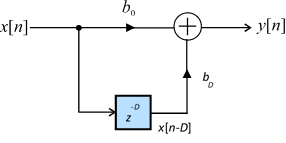 

Při hledání kořenů polynomu pak dostáváme pozici pólů a nul:

Póly: D-násobný kořen $z=0$

Nuly (pro $b_D =+0\ldotp 5,\textrm{symetrický}$): rovnoměrně po jednotkové kružnici vzdálené od sebe o $\frac{2\pi }{D}$ a **symetricky kolem **$\omega =0$ 

        $\omega =2\pi \frac{1}{2D},2\pi \frac{3}{2D},\ldotp \ldotp \ldotp ,2\pi \frac{2D-1}{2D}$ respektive $f=\frac{1}{2D}f_s ,\frac{3}{2D}f_s ,\ldotp \ldotp \ldotp ,\frac{2D-1}{2D}f_s$

Př.: D=5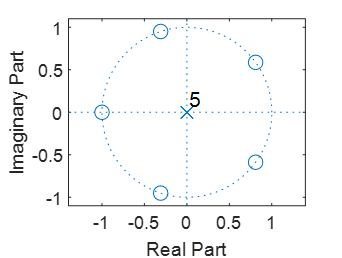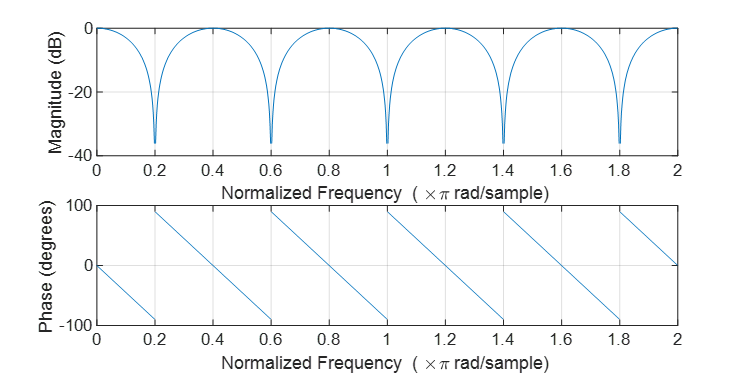

Nuly (pro $b_D =-0\ldotp 5$, antisymetrický): rovnoměrně po jednotkové kružnici vzdálené od sebe o $\frac{2\pi }{D}$ **s nulou v **$\omega =0$ 

        $\omega =0,2\pi \frac{1}{D},\ldotp \ldotp \ldotp ,2\pi \frac{D-1}{D}$ respektive $f=0,\frac{1}{D}f_s ,\ldotp \ldotp \ldotp ,\frac{D-1}{D}f_s$

Př.: D=5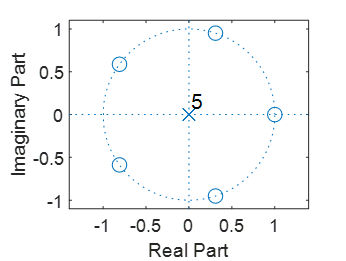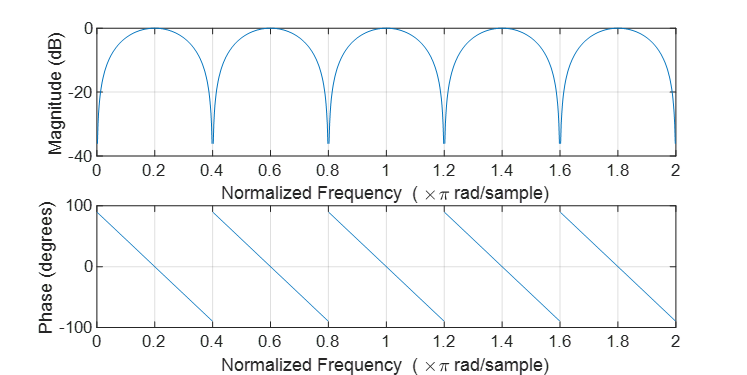

V přenosové charakteristice pak pozice nul vytváří pravidelné zádržná pásma (zářezy), buď s lichým nebo sudým násobkem normovaného kmitočtu $\omega_0$ respektive frekvence $f_0$. Je nutné si však uvědomit, že pokud musí být rozložení nul na jednotkové kružnici rovnoměrné, **musí být vždy správně zvolen i poměr filtrované frekvence a vzorkovací frekvence!** Tedy, D (řád filtru, počet zpožďovacích členů) musí být celé číslo!

$D=\frac{f_s }{2f_0 }$ pro $b_D =+0\ldotp 5$

$D=\frac{f_s }{f_0 }$ pro $b_D =-0\ldotp 5$

clear all

Při nahrávání elektrofyziologických signálů dochází skoro vždy ke kontaminaci signálu rušením. Hlavní komponentu tvoří síťové rušení **50 Hz a jeho liché násobky od spínaných zdrojů**, které se indukuje na proudových smyčkách na kabelech mezi vstupem (předzesilovač dekodéru) a snímacími elektrodami. 

Jaký typ hřebenového filtru je vhodný pro filtraci lichých násobků 50 Hz, symetrický nebo antisymetrický?

**Odpovězte:** symetrický

Př.: Načtěte signál stereo-EEG, který obsahuje záznam mozkové aktivity z mozkové oblasti zodpovědné za vznik epileptických záchvatů. Epileptiformní tkáň je i mimo záchvat schopna generovat interiktální epileptiformní výboje - ostré tranzienty následované pomalou vlnou. Signál je však silně zarušen síťovým brumem a "plave" z důvodu plovoucí reference. Odstraňte síťové rušení.

load('iEEG_izoline_50Hz.mat'); % signál stereo-EEG 
N = length(x);
T = N/fs;
t = linspace(0,T-1/fs,N);% t=... časová osa

Zobrazte signál a jeho odhad PSD:

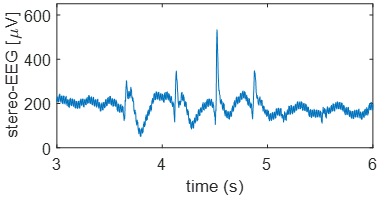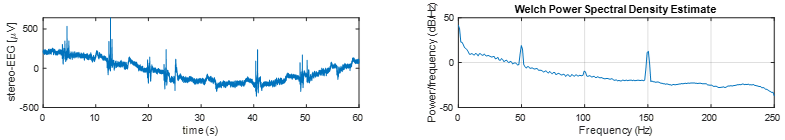

Pozn.: zobrazena jen polovina spektra $f\in \left\langle 0;\frac{f_s }{2}\right\rangle$.

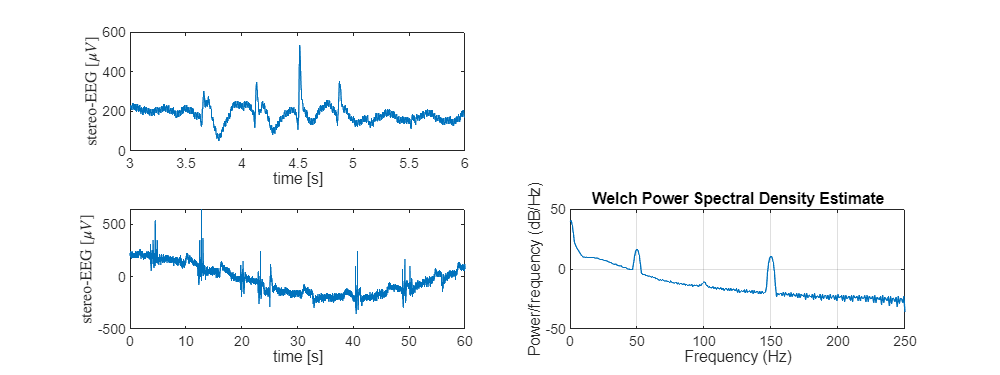


figure
set(gcf,'Position', [0 0 800 300])
subplot(221)
plot(t(t>3&t<6),x(t>3&t<6))
xlabel("time [s]")
ylabel('stereo-EEG $[\mu V]$', interpreter='latex')
subplot(223)
plot(t,x);
ylabel('stereo-EEG $[\mu V]$',Interpreter="latex")
xlabel('time [s]')
subplot(224)
pwelch(x,hamming(256),256/2,600,fs);

Navrhněte impulzní odezvu hřebenového filtru $b\left\lbrack n\right\rbrack$ délky $D+1$ pro filtraci lichcých násobků $f_0 =50\;\textrm{Hz}$, kde řád filtru odpovídá zpoždění $D$.


$$D=\frac{f_s }{2f_0 }$$



$$b\left\lbrack k\right\rbrack =\left\lbrace \begin{array}{ll}
0 & k\not= \left\lbrace 1,\;D-1\right\rbrace \\
0,5 & k=\left\lbrace 0,\;D\right\rbrace 
\end{array}\;k=0\;\ldotp \ldotp \ldotp D\right.$$


Pozn.: V teorii bylo výhodné první vzorek impulzní odezvy zančit jako $b_0$ (tj. v čase *t*=0). V MATLAB však indexujeme od $1$ po $D+1$.  

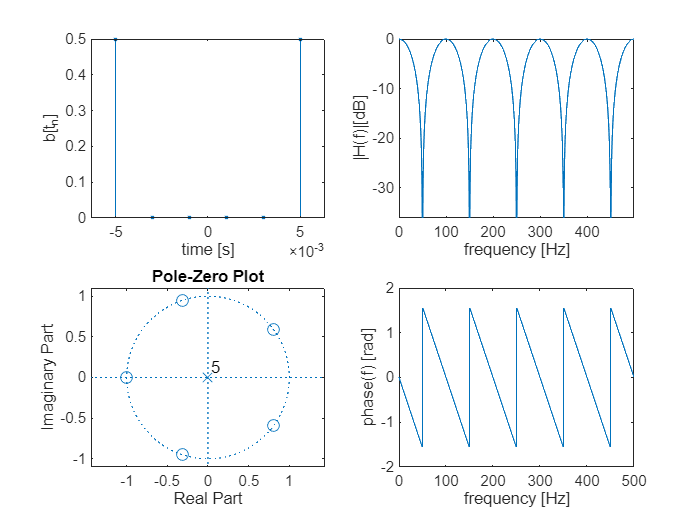

f0 = 50;
D = fs/(2*f0);
t_b = linspace(-D/(2*fs),D/(2*fs), D+1);
b = zeros(1,D+1);% b=zeros(...) - vektor délky impulzní odezvy 
b([1 end]) = [0.5 0.5] ;       % b([1 end])=...
[H,f]=freqz(b,1,1000, "whole",fs);
figure
subplot(221)
stem(t_b,b,'.')
ylabel("b[t_n]")
xlabel("time [s]")
subplot(222)
plot(f,20*log10(abs(H)))
xlabel("frequency [Hz]")
ylabel("|H(f)|[dB]")
axis tight
subplot(223)
zplane(b,1)
subplot(224)
plot(f,angle(H))
xlim([0 500])
xlabel("frequency [Hz]")
ylabel("phase(f) [rad]")

idx = (20*log10(abs(H)))<=-3 & (20*log10(abs(H)))>=-3.05;
boundaries = f(idx);
disp(boundaries(2) - boundaries(1))

    50



**Zobrazte frekvenční charakteristiku hřebenového filtru včetně impulzní odezvy a z-roviny:**

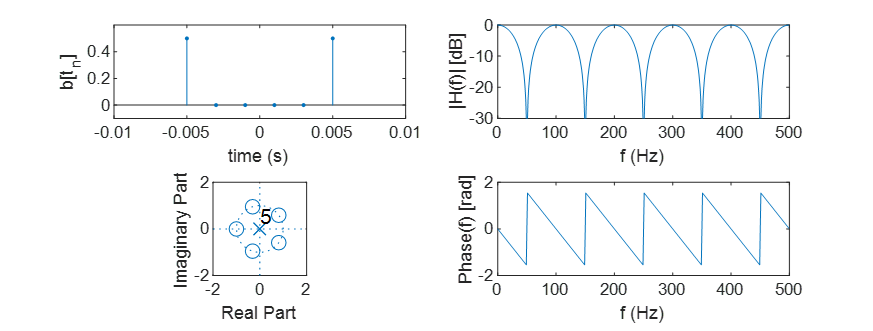

**Jaká je šířka zádržného pásma jednoho zářezu hřebenového filtru definovanou pro útlum pod -3 dB? Porovnejte s teoretickým odhadem dle vzorce **$\Delta f_{\textrm{stop}} \approx \frac{\sqrt{2}f_s }{\pi D}$

**Šířka zádržného pásma jednoho zářezu je: **

**odhadnutá výpočtem  45.02 Hz**

**změřená chrakteristiky  50 Hz **

**Filtrujte EEG signál hřebenovým filtrem lichých násobků 50 Hz.**

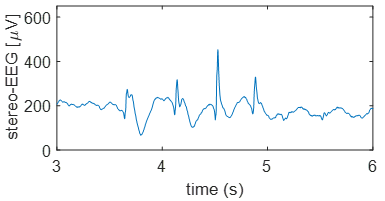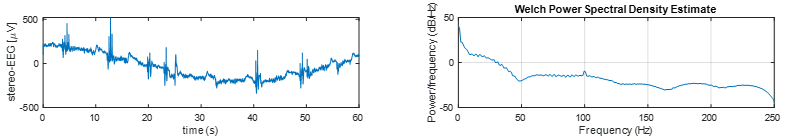

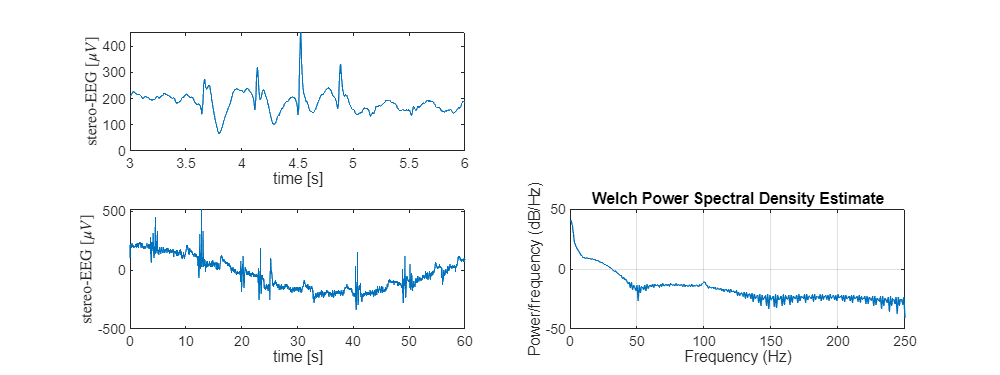

xf = filter(b,1,x)';
figure
set(gcf,'Position', [0 0 800 300])
subplot(221)
plot(t(t>3&t<6),xf(t>3&t<6))
xlabel("time [s]")
ylabel('stereo-EEG $[\mu V]$', interpreter='latex')
subplot(223)
plot(t,xf);
ylabel('stereo-EEG $[\mu V]$',Interpreter="latex")
xlabel('time [s]')
subplot(224)
pwelch(xf,hamming(256),256/2,600,fs);

Pozn.: Ačkoli hřebenový filtr odstraňuje všechny liché násobky 50 Hz (dle návrhu), **šířka zádržného pásma je velká** a může odstraňovat i důležeté komponenty signálu. Hřebenový filtr je používán více v technických aplikacích nežli v medicínských, kde je vyžadováno minimální zkreslení signálu pro prohlížení.   

#### **Filtrace nízkofrekvenčních složek**

Pro filtraci kolísání izolinie (viz minulé cvičení) využijte horní propusti (HP) s mezním kmitočtem 0.5 Hz. 

V LTI systému platí linearita, proto můžeme filtry řadit libovolně za sebe a v jakémkoli pořadí, výsledek bude vždy stejný. Proto navážeme na předchozí filtraci lichých násobků 50 Hz hřebenovým filtrem a přidáme další filtraci izolinie. 

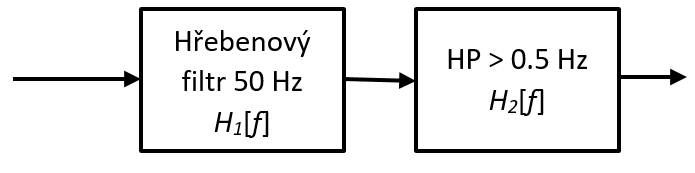

Navrhněte horní propust (HP) s mezním kmitočtem $f_0 =0\ldotp 5\;\textrm{Hz}$. Využijte návrhu dle $\textrm{sinc}\left(\;\right)$ funkce, nebo již jednodušeji implementací v signal processing toolboxu: `fir1()`. Řád filtru $M$odhadněte metodou pokusu a omylu, vycházejte z dřívější zkušenosti (v řádu stovek až tisíců). Uvědomte si, že řád filtru **musí být sudý**, aby prototypové okno bylo symetrické kolem jednotkového impulzu $b_{\textrm{HP}} \left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -\textrm{sinc}\left(\pi \omega_0 n\right)$.


$$\omega_0 =\frac{2f_0 }{f_s };\;\omega_0 \in \left\langle 0,1\right\rangle \;\textrm{pokud}\;f_0 <\frac{f_s }{2}\;\ldotp \ldotp \ldotp \textrm{normovaný}\;\textrm{kmitočet}$$


Pomocí funkce `freqz()` si zobrazte přenosovou charakteristiku a ověřte, zda jeho mezní kmitočet $f_0 =0\ldotp 5\;\textrm{Hz}$ (-3 dB) odpovídá Vašim požadavkům. Pokud ne, zvyšte řád.

**Kompenzujte fázové zpoždění. **Z teorie víme, že kompenzace lineárního fázového zpoždění FIR filtru se symetrickou/antisymetrickou impulzní odezvou lze posunutím signálu zpět o polovinu řádu fitru $\frac{M}{2}$. Při řazení filtrů pak kompenzujeme celkové zpoždění kaskády $\frac{D+M}{2}$, kde *D* je řád hřebenového fitlru a *M* řád horní propusti. Zde použitý hřebenový filtr má řád **lichý** a posun o půlvzorek nelze realizovat. Řešením (sice ne zcela přesným) je kompenzace o $\frac{D+M}{2}$ zaokrouhleno dolů, tedy posunem o `floor((D+M)/2)` vzorků. 

Př.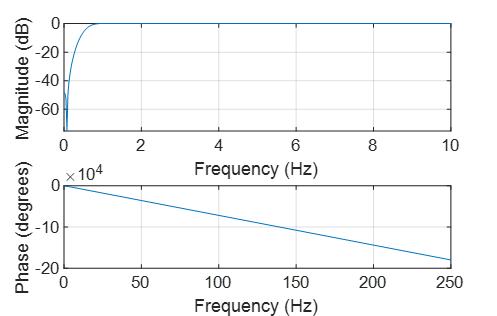V závislosti na zvoleném řádu se může lišit.

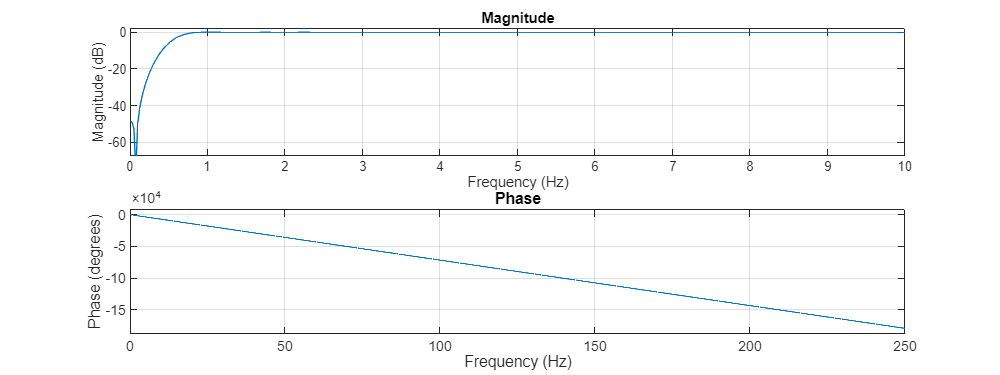

M = 2000;
f0 = 0.5;
w0 = 2*f0/fs;
b_HP=fir1(M,w0,'high'); % impulzní odezva (koeficienty filtru) pro horní propust ('high')
freqz(b_HP,1,10e3,fs); % frekvenční charakteristika filtru (10e3 bodů pro vykreslení)
xlim([0 10])% zoom x-osy        

**Filtrujte dolní propustí signál již filtrovaný hřebenovým filtrem:** 

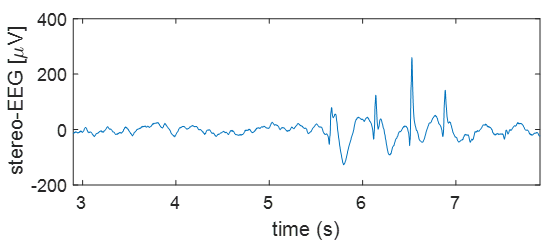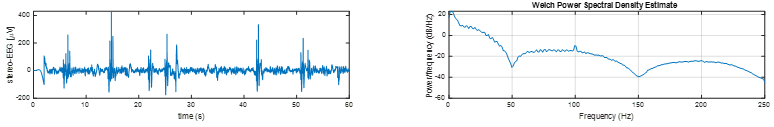

Zpoždění závisí na vámi zvoleném řádu filtru HP.

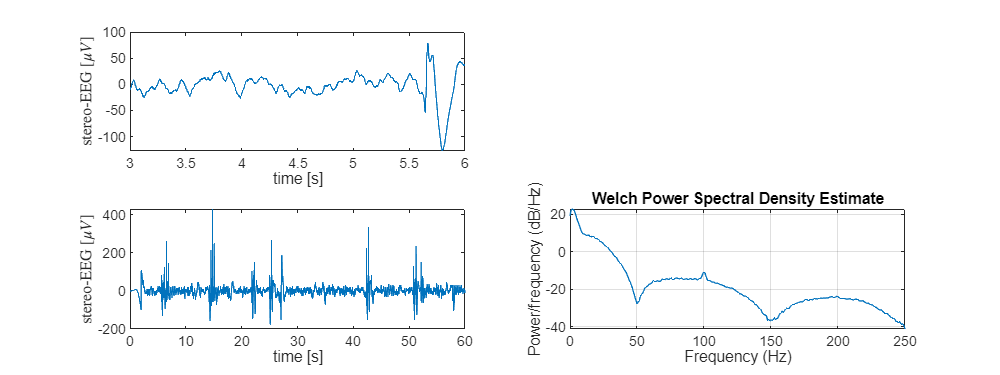

        % b_hp=... horní propust
[v, id] = max(x); %hrot před filtrací
[v_comb, id_comb] = max(xf); %hrot po hřebenovém filtru
xf = filter(b_HP,1,xf)';
[v_comb_HP, id_comb_HP] = max(xf); %hrot po filtraci hřebenem i horní propustí

figure
set(gcf,'Position', [0 0 800 300])
subplot(221)
plot(t(t>3&t<6),xf(t>3&t<6))
xlabel("time [s]")
ylabel('stereo-EEG $[\mu V]$', interpreter='latex')
subplot(223)
plot(t,xf);
ylabel('stereo-EEG $[\mu V]$',Interpreter="latex")
xlabel('time [s]')
subplot(224)
pwelch(xf,hamming(256),256/2,600,fs);

disp(['hrot před filtrací je v čase ' num2str(id/fs)  ' sekund'])

hrot před filtrací je v čase 12.786 sekund


disp(['hrot po filtraci hřebenovým filtrem je v čase ' num2str(id_comb/fs) ' sekund'])

hrot po filtraci hřebenovým filtrem je v čase 12.794 sekund


disp(['hrot po filtraci hřebenovým filtrem a horní propustí je v čase '  num2str(id_comb_HP/fs)  ' sekund'])

hrot po filtraci hřebenovým filtrem a horní propustí je v čase 14.794 sekund


#### **Kompenzace zpoždění FIR filtru**

Signál procházející LTI systémem se na výstupu zpožďuje. To lze vizuálně spatřit na původním EEG signálu a výsledku filtrace (hřebenový filtr + izolinie). Najděte si kurzorem např. největší epileptiformní hrot v původním nefiltrovaném signálu v 4,5 s. Identifikujte ten samý hrot po filtraci hřebenovým filtrem  a posléze filtrací horní propustí:

**Hrot je v původním EEG v **`12.786`** sekundě**

**Hrot je po hřebenové filtraci v **`12.794`** sekundě**

**Hrot je po hřebenové filtraci a horní propusti v **`14.794`** sekundě**

Protože jsme při návrhu vždy dodržovali symetrii impulzní odezvy fitru $b\left\lbrack -k\right\rbrack =b\left\lbrack k\right\rbrack$, zpoždění je přes frekvence lineární (harmonické složky se posouvají o stejný počet vzorků). Proto lineární fázové zpoždění můžeme kompenzovat posunem výstupního signálu o polovinu řádu filtru $\frac{M}{2}$. **Pozor: EEG signál procházel dvěma filtry (hřebenový a HP) a na každém se signál zpozdil. **Zpoždění LTI systému proto odpovídá $\Delta =\frac{\left(D+M_{\textrm{HP}} \right)}{2}$.

delta = floor((D + M)/2)    % delta = ...

delta = 1002

delta_s = delta/fs

delta_s = 2.0040

**Jaké je zpoždění **$\Delta$**: 1002  vzorků, tj.  2.004  sekund?**

Ořízněte začátek filtrovaného EEG signálu o $\Delta$ vzorků, čímž jej posuneme zpět v čase:

**Kompenzujte zpoždění filtru:**

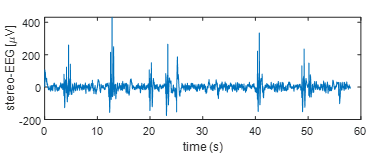

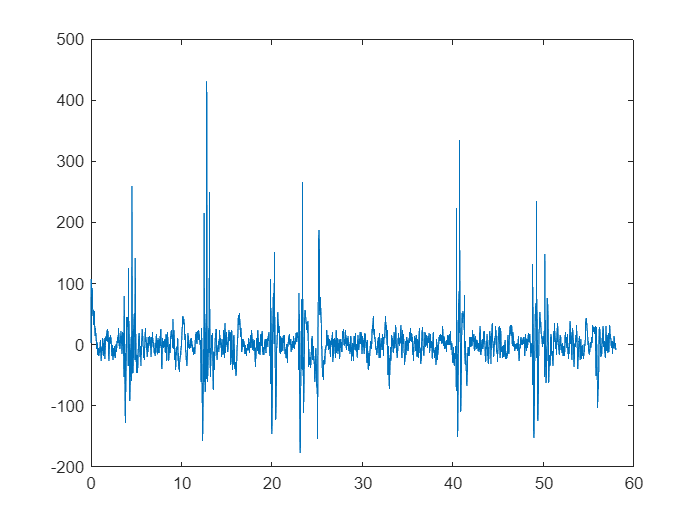

x2 = xf(delta:end);
t = t(1:end - delta +1);
figure
plot(t,x2)

[v , id] = max(x2)

v = 430.4055

id = 6396

disp(['hrot je po kompenzaci zpoždění v čase ' num2str(id/fs)  ' sekund'])

hrot je po kompenzaci zpoždění v čase 12.792 sekund


**Znovu ověřte polohu výboje.**

**Hrot je v původním EEG v 12.786 sekundě**

**Hrot je po filtraci a kompenzaci zpoždění systému v 12.792 sekundě**

**Případný rozdíl zdůvodněte: **hřebenový filtr nemá zpoždění v celých vzorcích, proto ho nelze dokonale vykompenzovat. Filtrace také může upravit tvar hrotu a posunout jeho vrchol

### 2) Filtr klouzavých průměrů a diferenciátor

clear all

#### **Filtr klouzavých průměrů (MA-filtr),**

anglicky Moving Average, patří mezi základní FIR filtry a ve své praxi jej pro jeho jednoduchost budete využívat možná nejčastěji. Jak již název napovídá, filtr je navržen tak, aby se maska filtru (impulzní odezva) klouzala po signálu a na výstupu vracela průměrnou hodnotu z vybíraných vzorků. Tento filtr se používá k vyhlazení křivek a odšumování signálů. Jedná se tedy charakterem o dolní propust (DP), která odstraňuje rychlé komponenty signálu. Impulzní odezva MA-filtru délky $K$ (řád filtru $M=K-1$) je konstantní (obdélníková) a velikost amplitudy jednotlivých koeficientů odpovídá zlomku délky odezvy $b\left\lbrack k\right\rbrack =\frac{1}{K}$. Pokud v zápisu diferenční rovnice FIR filtru za koeficienty filtru $b_k$ dosadíme konstanty $\frac{1}{K}$, je zřejmé, že rovnice bude odpovídá aritmetickému průměru vzorků signálu klouzavého okna. Obdélníková impulzní odezva MA-filtru je vždy symetrická a zpoždění filtru je tedy lineární pro sudý i lichý řád $M$, avšak pro snadnou kompenzaci zpoždění volíme řád raději sudý.


$$k\in \left\langle 0,K-1\right\rangle ;1\ldotp \textrm{vzorek}\;k=0,\;\textrm{poslední}\;K-1$$



$$\begin{array}{l}
y\left\lbrack n\right\rbrack *b\left\lbrack k\right\rbrack :\;y\left\lbrack n\right\rbrack =\sum_{k=0}^{K-1} b\left\lbrack k\right\rbrack x\left\lbrack n-k\right\rbrack \;\\
y\left\lbrack n\right\rbrack =b\left\lbrack 0\right\rbrack x\left\lbrack n\right\rbrack +b\left\lbrack 1\right\rbrack x\left\lbrack n-1\right\rbrack +\ldotp \ldotp \ldotp +b\left\lbrack K-1\right\rbrack x\left\lbrack n-\left(K-1\right)\right\rbrack \;\\
y\left\lbrack n\right\rbrack =\frac{1}{K}x\left\lbrack n\right\rbrack +\frac{1}{K}x\left\lbrack n-1\right\rbrack +\ldotp \ldotp \ldotp +\frac{1}{K}x\left\lbrack n-\left(K-1\right)\right\rbrack \\
y\left\lbrack n\right\rbrack =\frac{1}{K}\sum_{k=0}^{K-1} x\left\lbrack n-k\right\rbrack 
\end{array}$$


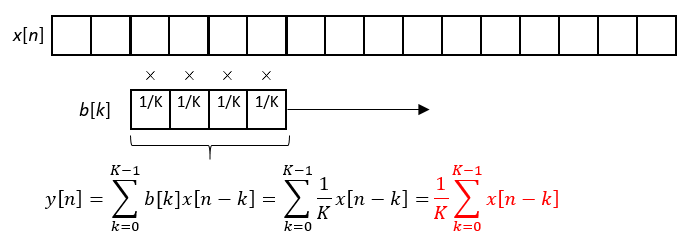      

**Krokoměr:**

Funkci krokoměru dnes zastupuje většina zařízení obsahující elektronické obvody tříosého akcelerometru (chytré náramky, telefony, hodinky a jiná nositelná elektronika). Z analýzy pohybu zařízení lze dovodit pohyb jeho nositele např. při chůzi a sportu, ale také např. pády seniorů či jinak zdravotně postižených osob pro přivolání pomoci. 

Ukázkový signál byl zaznamenán mobilním telefonem v zadní kapse kalhot při běžné chůzi po městské zástavbě. 

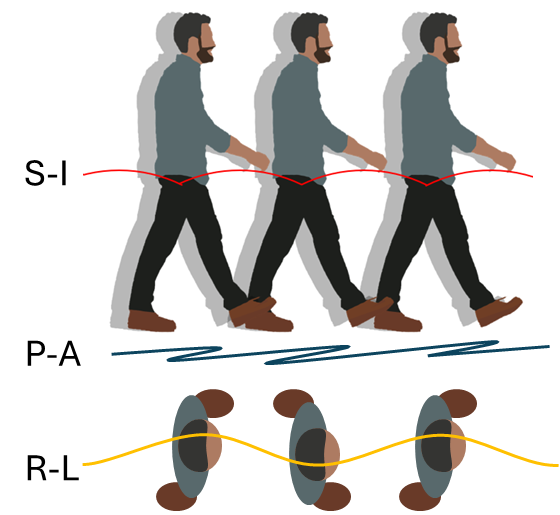

**Načtěte a zobrazte signál z akcelerometru ve všech třech osách:**

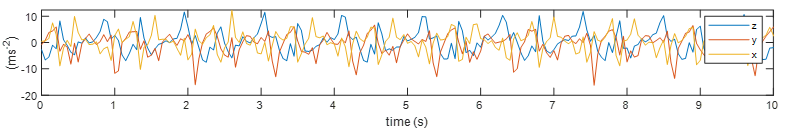

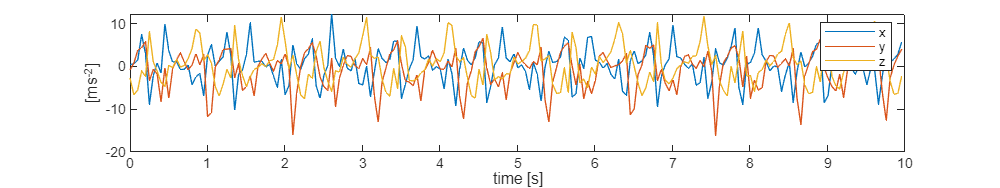

load('walking.mat'); % obsahuje signál akcelerometru v osách "x", "y", "z" a vzorkovací kmitočet "fs"
t = linspace(0, length(x)/fs,length(x));        % t=... časová osa
idx = t<=10;
figure
set(gcf,'Position', [0 0 800 150])

plot(t(idx),x(idx),t(idx),y(idx),t(idx),z(idx))
legend('x','y', 'z')
ylabel('[ms^{-2}]')
xlabel("time [s]")

Oproti signálu z 5. cvičení, nejsou osy akcelerometru orientovány ve směru pohybu: superior(+):inferior(-), anterior(+):posterior(-), vlevo(+):vpavo(-), senzor v telefonu je v 3D prostoru pootočen. Proto jsou jednotlivé složky pohybu promítány do všech os a nelze obecně vybrat jednu, ve které se chůze detekuje nejlépe. Spočtěte proto celkové zrychlení $g$ jako Euklidovskou vzdálenost mezi signály.

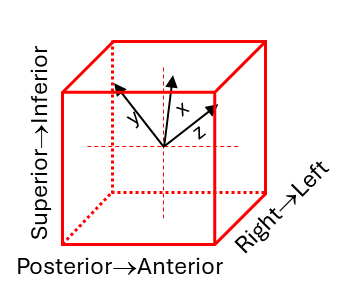


$$g=\sqrt{x^2 +y^2 +z^2 }$$


Výsledek zobrazte

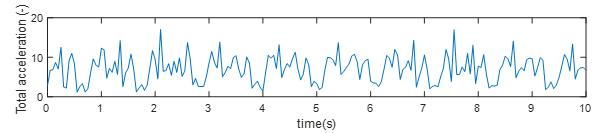

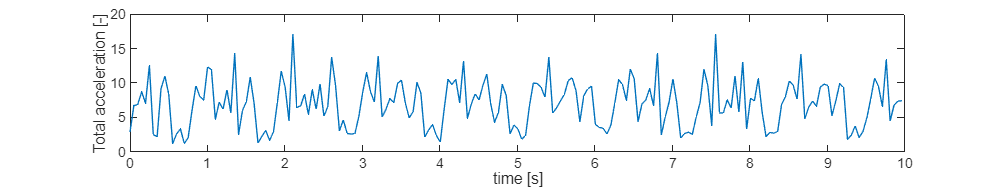

g = (x.^2 + y.^2 + z.^2).^(1/2);
figure
set(gcf,'Position', [0 0 800 150])
plot(t(idx), g(idx))
ylabel("Total acceleration [-]")
xlabel("time [s]")

V celkové akceleraci jsou patrné překmity způsobené otřesy při došlapu a pohybem zařízení v kapse probanda. Je tedy nutno tyto překmity vyhladit filtrem klouzavých průměrů (**MA-filtrem**)

**Navrhněte MA-filtr s velikostí filtrační masky tak, aby dostatečně vyhladila signál, ale zároveň byla kratší než polovina periody jednoho cyklu chůze, tj. 0.5 s maska:**

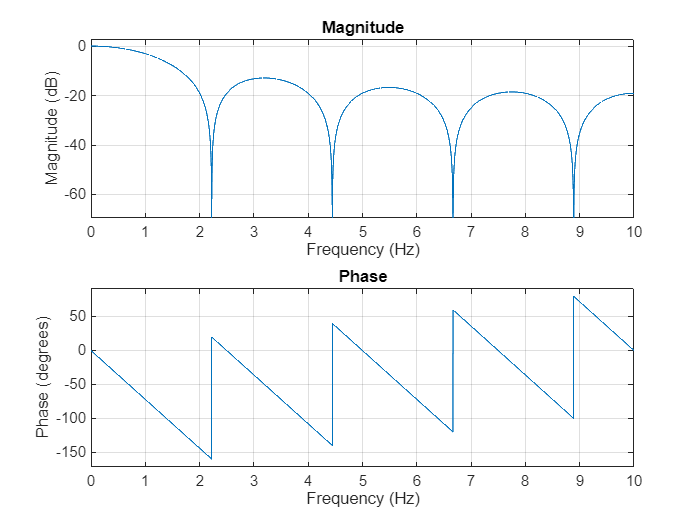

T = 0.5;        % T=... délka masky v sekundách (nápověda: vyzkoušejte délky 0.1 až 0.5 sekundy)
K = round(T*fs);        % K=... velikost klouzavého okna ve vzorcích přepočteno dle fs ze
        %       sekund na celé vzorky round(), řád M=K-1 (M by měl být sudý, 
        %       tedy K liché pro případnou kompenzaci zpoždění)
K = K - (1-mod(K,2));
bMA=ones(K,1)/K; % impulzní odezva MA-filtru
figure
freqz(bMA,1,1e4,fs); % frekvenční charakteristika MA-filtru. 

Př. pro 0.5 s masku: V detailu přenosové charakteristiky je patrné, že strmost dolní popusti jako MA-filtru je oproti $\textrm{sinc}\left(\;\right)$ prototypu malá i pro vysoké řády filtru $M=K-1$. Zářez prvního laloku ale odpovídá 2 Hz, což koresponduje s délkou masky $\frac{1}{0\ldotp 5\;\mathrm{s}}$. 

Pozn.: pro vyhlazení bychom tedy mohli použít i jakoukoli DP s mezním kmitočtem $f_0 <2\;\textrm{Hz}\ldotp$ Pro případ nedostatečného vyhlazení doporučujeme MA-filtr použít dvakrát po sobě (s dvojnásobným fázovým zpožděním).

Př.: $M\approx 0\ldotp 5s$

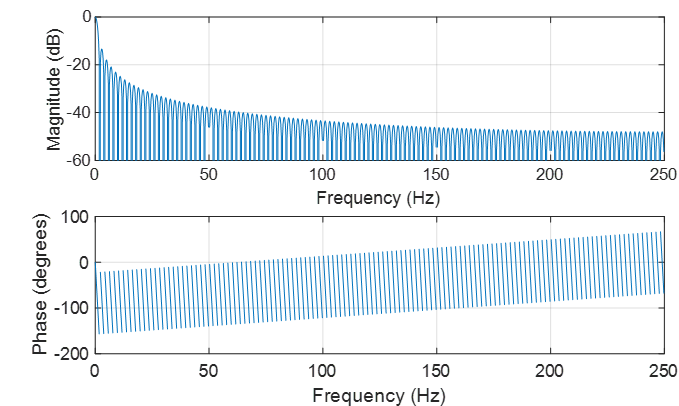  Detail: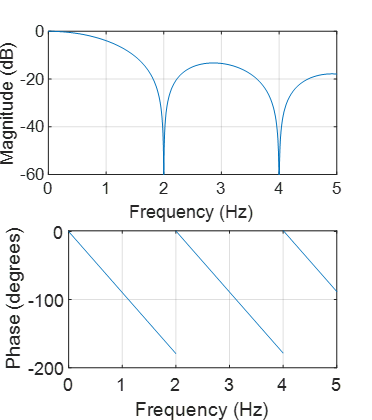

**Vyhlaďte signál MA-filtrem:**

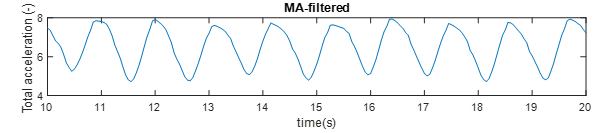

Pozn.: můžete realizovat kompenzaci zpoždění filtru, ale pro zadanou úlohu není potřebné, proto není vyžadována

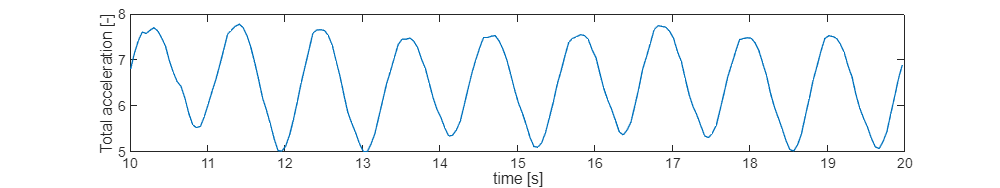

gf = filter(bMA,1,g);
gf = filter(bMA,1,gf);
idx = t>10 & t<20;
figure
set(gcf,'Position', [0 0 800 150])
plot(t(idx),gf(idx))
xlabel('time [s]')
ylabel("Total acceleration [-]")

**Akcelerace a decelerace**

Profil chůze mezi jednotlivými kroky je charakterizován zpomalováním a zrychlováním. Počet kroků tedy bude odpovídat počtu zrychlení nebo počtu zpomalení.

Odstraňte z vyhlazeného průběhu celkového zrychlení stejnosměrnou složku $x-\textrm{mean}\left(x\right)$:

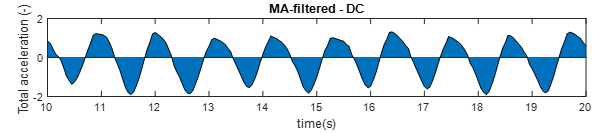

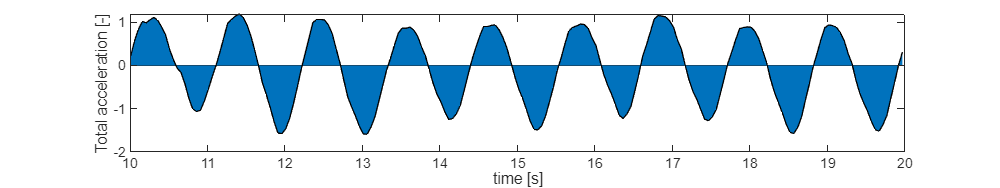

gf = gf-mean(gf);
figure
set(gcf,'Position', [0 0 800 150])
area(t(idx),gf(idx))
xlabel('time [s]')
ylabel("Total acceleration [-]")

Detekujte jednotlivé úseky akcelerace tak, že kladným úsekům (akcelerace) přiřadíte 1 (true) a negativním (decelraci) 0 (false).

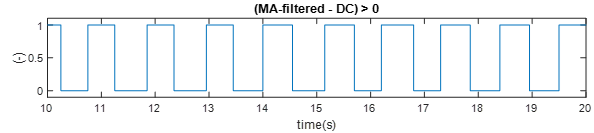

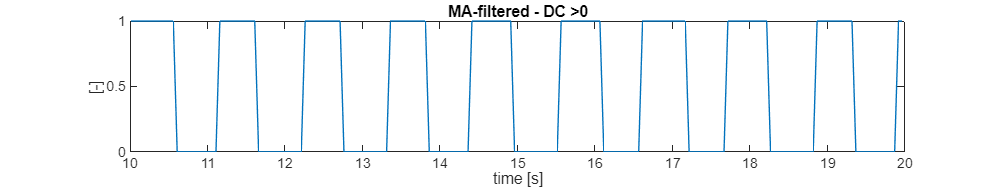

y = zeros(1,length(gf));
idx2 = gf>0;
y(idx2) = 1;
figure
set(gcf,'Position', [0 0 800 150])
plot(t(idx),y(idx))
xlabel('time [s]')
ylabel("[-]")
title('MA-filtered - DC >0')

#### **Diferenciátor**

Diferenciátor si lze představit jako klouzavá diference mezi sousedními vzorky. 

Obecná diference má předpis $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack$, což odpovídá i diferenční rovnici filtru:


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =b_0 x\left\lbrack n\right\rbrack +b_1 x\left\lbrack n-1\right\rbrack ,\;\textrm{kde}\;\mathbf{b}=\left\lbrace 1;-1\right\rbrace \\
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack \\
Y\left\lbrack z\right\rbrack =X\left\lbrack z\right\rbrack -z^{-1} X\left\lbrack z\right\rbrack \\
H\left\lbrack z\right\rbrack =\frac{Y\left\lbrack z\right\rbrack }{X\left\lbrack z\right\rbrack }=\frac{1-z^{-1} }{1}=\frac{z-1}{z}
\end{array}$$


Póly: $z=0$

Nuly: $z=1$

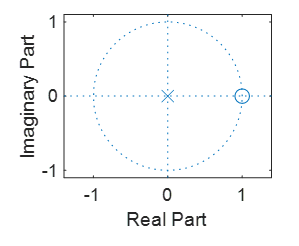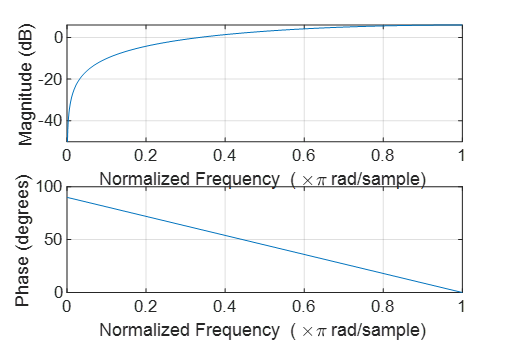

Pozn.: Diference signálu zvýrazňuje rychlé změny (skoky) a konstantní hodnoty (stejnosměrná složka) jsou rovny nule. 

**O jaký typ filtru se jedná?**

horní propust

**Detekce náběžných hran**

K detekci náběžných hran využijeme vlastností kladné diference u rostoucí funkce (záporné u klesající). Zdiferencujte obdelníkový signál úseků akcelerace a decelerace. 

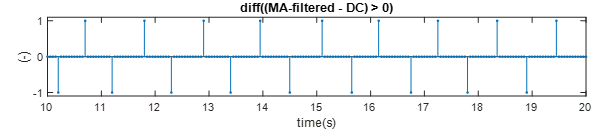 

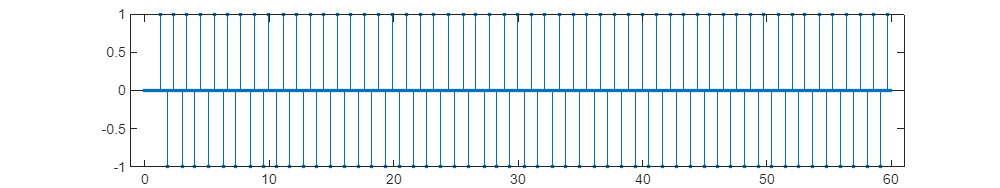

% 1) Příklad použití (filtrem) ------------
b_diff=[1 -1]; % řád filtru M=1
yf=filter(b_diff,1,y); % diference
% kompenzace zpoždění
yf=yf(2:end);
tf=t(1:end-1);
figure
set(gcf,'Position', [0 0 800 150])
stem(tf(idx),yf(idx),'.')

**Krokoměr:**

Spočtěte počet kroků pomocí celkového počtu náběžných nebo sestupných hran.

Np = sum(yf == 1)        

Np = 54

Při tělesné výšce 183 cm probanda odpovídá jeho průměrná délka kroku 77 cm. Spočtěte, jakou vzdálenost proband asi ušel a jakou rychlostí se pohyboval. 

**Pomocí funkcí **`disp()`** a **`num2str()`** vypište výsledek:**

disp(['bylo změřeno ' num2str(Np) ' kroků za ' num2str(tf(end)) ' sekund'])

bylo změřeno 54 kroků za 59.9 sekund


disp(['Proband ušel asi ' num2str(Np*0.77) ' metrů'])

Proband ušel asi 41.58 metrů


disp(['Jeho průměrná rychlost byla asi ' num2str(Np*0.77/tf(end)*3.6) ' km/h'])

Jeho průměrná rychlost byla asi 2.499 km/h


**Bylo změřeno 54 kroků za 59.9 sekund.**

**Proband ušel asi 41.58 metrů.**

**Jeho průměrná rychlost byla asi 2.499 km/h. **

**Shrnutí algoritmu detekce náběžných a sestupných hran:**

Pochopte a zapamatujte si jednotlivé kroky postupu detekce náběžných a sestupných hran, v budoucích cvičeních jej budeme v různých podobách využívat 

- filtrace signálu (zde vyhlazení MA-filtrem)

- parametrizace (zde akcelerace/decelerace, jindy např. překročení detekčního prahu)

- detekce náběžných a sestupných hran diferencí obdelníkového signálu

## Bonus (2b)

Pro uvedené koeficienty *b*[*n*] vytvořte:

- Mřížkovou strukturu,

- diferenční rovnici a přenosovou funkci $H\left\lbrack z\right\rbrack$

- určete pozici nul a pólů, které zakreslete do jednotkové kružnice v z-rovině,

- načrtněte amplitudovou přenosvou charakteristiku dle membránového modelu,

- určete typ propusti (zádrže; dolní propust, horní propust, ...).

1. ${\mathit{\mathbf{b}}}_1 =\left\lbrace 0\ldotp 5;\;-0\ldotp 5\right\rbrace$

2. ${\mathit{\mathbf{b}}}_2 =\left\lbrace 0,5;0;0;0;-0,5\right\rbrace$

**Řešení na papíře odevzdávejte oskenované/ofocené společně s kódem.**